## Energy band diagram for the MOS-C

### Parameters for the energy band diagram at the threshold (strong inversion is starting)

k = 1.380649e-23; % Boltzmann constant (J/K)
T = 300; % Absolute temperature (K)
q = 1.602176634e-19; % Elementary charge (C)
epsilon_0 = 8.854187817e-12; % Vacuum permittivity (F/m)
epsilon_ox = 3.9; % Relative permittivity of SiO2

% Given values
C_ox = 20e-12; % Oxide capacitance (F)


#### Compuation assumptions: Vg = 0.7V, and A = 3e-4 m^2

V_G = 0.7; % Assumed gate voltage (V)
A = 3e-4; % Assumed area of the MOS-C (m^2)


#### Assume flat band voltage V_FB to be 0 for simplicity

V_FB = 0; 


#### Assume the effective mass of electrons in the conduction band (Si) for Nc calculation

m_e = 9.10938356e-31; % Electron rest mass (kg)
m_n_star = 0.26 * m_e; % Effective mass for electrons in silicon


#### Calculate the effective density of states in the conduction band (Nc) for silicon at T = 300 K

Nc = 2 * ((2 * pi * m_n_star * k * T) / (h ^ 2)) ^ (3 / 2) / 1e6; % Convert m^-3 to cm^-3


#### Assume a typical donor concentration Nd for n-type silicon

Nd = 1e16; % Donor concentration (cm^-3)


#### Calculate surface potential ψs assuming strong inversion condition ψs ≈ 2 * kT/q

V_T = k * T / q; % Thermal voltage (V)
psi_s = 2 * V_T; % Surface potential under strong inversion (V)


#### Calculate the conduction band edge Ec at the surface relative to the Fermi level using ψs

Ec_surface = q * psi_s; % (J)


#### Calculate Fermi level position relative to the conduction band edge at the surface

Ef = Ec_surface - k * T * log(Nc / Nd); % (J)

% Convert Ef from Joules to electron volts (eV) for the final result
Ef_eV = Ef / q; % (eV)

% Output the result
fprintf('The Fermi level Ef relative to the conduction band edge at the surface is %.4f eV\n', Ef_eV);

The Fermi level Ef relative to the conduction band edge at the surface is -0.0984 eV


### Energy levels at the semiconductor surface under strong inversion

Ec_surface = -q * phi_s % Conduction band energy at the surface

Ec_surface = -1.1445e-19

Ef_surface = Ef_eV % Fermi level energy at the surface (reference)

Ef_surface = -0.0984

Ev_surface = Ec_surface - Eg % Valence band energy at the surface

Ev_surface = -1.1200

### Energy levels in the bulk semiconductor (away from surface)

Ec_bulk = -q * Vt * log(Nd/Ni); % Conduction band energy in the bulk
Ev_bulk = Ec_bulk - Eg; % Valence band energy in the bulk
Ef_bulk = Ef_eV; % Fermi level in the bulk (reference)


#### Create the energy band diagram

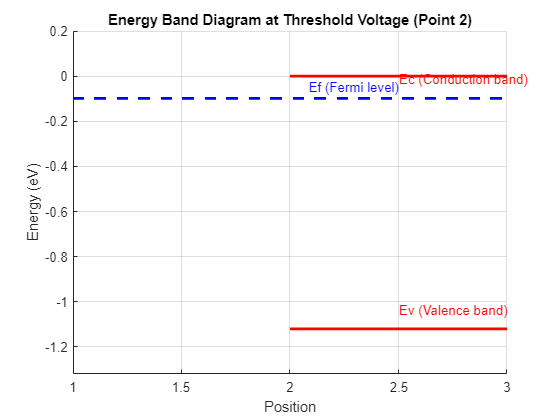

figure;
hold on;
% Draw the semiconductor bands
plot([2, 3], [Ec_surface, Ec_bulk], 'r-', 'LineWidth', 2); % Conduction band
plot([2, 3], [Ev_surface, Ev_bulk], 'r-', 'LineWidth', 2); % Valence band
% Draw the Fermi level
plot([1, 3], [Ef_surface, Ef_bulk], 'b--', 'LineWidth', 2); % Fermi level

% Set the plot limits and labels
xlim([1, 3]);
ylim([Ev_surface - 0.2, Ec_surface + 0.2]);
xlabel('Position');
ylabel('Energy (eV)');
title('Energy Band Diagram at Threshold Voltage (Point 2)');

% Annotate the plot
text(2.5, Ef_surface + 0.05, 'Ef (Fermi level)', 'Color', 'blue', 'HorizontalAlignment','right');
text(2.5, Ec_surface - 0.05, 'Ec (Conduction band)', 'Color', 'red', 'VerticalAlignment', 'baseline');
text(2.5, Ev_surface + 0.05, 'Ev (Valence band)', 'Color', 'red', 'VerticalAlignment', 'bottom');

% Finish the plot
hold off;
grid on;